# Introducing Iterative Reconstruction with Spiral Acquistions

Alex Cerjanic (acerj@udel.edu)

Adapted from Mark Chiew's (mark.chiew@ndcn.ox.ac.uk) "Non-Cartesian MR Image Reconstruction Without Dependencies" available at [https://users.fmrib.ox.ac.uk/~mchiew/docs/recon_tutorial_01.html.](https://users.fmrib.ox.ac.uk/~mchiew/docs/recon_tutorial_01.html.) 

**Learning Objectives:**

- Understand why ill-conditioning is a problem in non-Cartesian reconstruction

- Understand how to obtain the condition number of an image reconstruction problem where the system matrix is obtainable or given

- Understand how to obtain the condition number of a reuglarized image reconstruction where the direct solution is obtainable

- Understand an example of direct regularized image reconstruction

- Understand an example of iterative regularized image reconstruction

#### Disclaimers: 

- The methods employed below are for pedogogical purposes only. They are slow, memory hungry, and extremely brittle for practical applications.

- We commit the inverse crime without remorse and with willful recidivism

- We intentionally neglect issues such as sampling efficiency, field inhomogeneity, or other practical effects in these examples. Please do not make general inferences about the strengths and weaknesses of Cartesian vs. non-Cartesian from these examples.

## Define our test object

To begin, we need a slice of brain. As we cannot assume that you will donate, dear reader, we must start with a numerical phantom. To simplify our problem, we can start with the EPFL analytical brain phantom which can be obtained from [http://bigwww.epfl.ch/algorithms/mriphantom/.](http://bigwww.epfl.ch/algorithms/mriphantom) This generates a single slice of brain at any resolution desiered as it is defined in terms of vectors and splines. 

We will start with a 64 x 64 matrix size image to make the problem tractable. Ideally, in later discussions we will address ways that larger problems are made tractable.  I'll table that discussion for today.

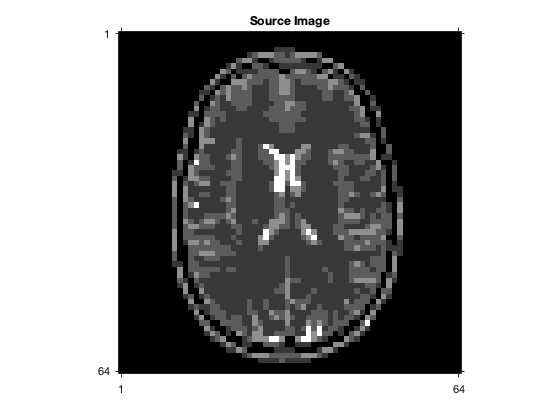

N_x = 64;           % size of image

DefineBrain; % Using EPFL Analytical Brain Phantom
x = rot90(RasterizePhantom(Brain,[N_x, N_x],1));

% show our source image
figure();im(x),colormap gray; title('Source Image');drawnow;

Great! Now we have an image to start. We will start with a 2D imaging case, just to show how everything works.

## Defining a 2D Cartesian Imaging Problem

To define a 2D Cartesian imaging problem, we need to define some quantities.

$k_x$, $k_y$ are the k-space coordinated in x and y respectively. $N_k$ is the number of k-space samples. $N_x$ is the number of data points in the image domian. L We'll use the meshgrid function to generate a Cartesian grid of samples and image domain points. Just to prove to ourselves that we a nicely defined grid, we'll plot it.

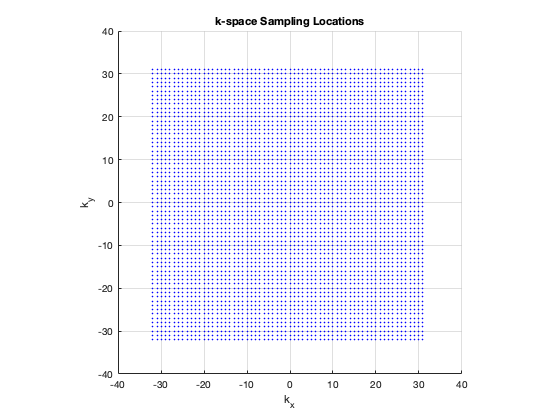

[k_x, k_y] = meshgrid(-N_x/2 : N_x/2 - 1);
N_k = length(col(k_x));

[xidx, yidx] = meshgrid(-N_x/2 : N_x/2 - 1);  % x- and y-coords with "isocentre" at the N_x/2+1 index
xidx = xidx./N_x; %Scaling the window from 0.5 to -0.5
yidx = yidx./N_x;

% show scatterplot of trajectory
figure();scatter(k_x,k_y,5,'filled','b');axis square;grid on 
xlabel('k_x');ylabel('k_y');title('k-space Sampling Locations');drawnow;

## Define discrete Fourier encoding matrix

To simulate an MRI experiment, we need to account for how MRI encodes data in k-space. 

Below we have the expression for the Fourier encoding for a single point in k-space. Note that we are looping over all image space points to calculate the value of the data in k-space. 


$$y_i =\sum_{l=i}^{N_x } x_{i\;} \exp \left(j\;2\pi \;\left(\overrightarrow{{\mathit{\mathbf{k}}}_i } \bullet \overrightarrow{{\mathit{\mathbf{r}}}_l } \right)\right)$$


A nice way to re-write this multiplication is as row-column multiplication. The column is the image data, $\overrightarrow{\mathit{\mathbf{x}}}$, and the row would be a row of exponentials corresponding to those in the equation above. If we stack those, rows, we will obtain a matrix, $F$. 

The letter chosen was not arbitrary, nor was it vulgar. This matrix is the DFT matrix, otherwise known as the Fourier matrix. Any multiplication of a column of data by this matrix will give the DFT of that data. One conceptual point is that the data can be in any dimensions, even though the matrix will always be two dimenional. This is because the shape of the matrix is defined by the matrix-vector multiplications.

 We'll construct the Fourier matrix in code below. This is very slow code, so there is a clever line (that I did not come up with) to make this more tractable in MATLAB. If you are so inclined, you can look at the Fourier bases in the matrix by isolating, reshaping and plotting rows in the Fourier matrix. This is left as an exercise to you, dear reader. (I've always wanted to write this.)



% Loop over each k-location to construct its required spatial phase modulation
F_cart = zeros(N_k, N_x, N_x);
for i = 1:N_k
    F_cart(i,:,:) = exp(1j*2*pi*(k_x(i)*xidx+k_y(i)*yidx));   % 2D Fourier exponential
end

F_cart = reshape(F_cart, N_k, []);    % reshape F so that each row is a single k-space encoding

% show an example encoding
%figure();im(angle(reshape(F(N_k/2,:),N_x,N_x)),[-pi pi]), colormap hsv ; 
%title('Phase of Example 2D Fourier Encoding Modulation');colorbar();drawnow;

## Apply forward model to our phantom image

For those who are particularly computationally oriented or scrupuously law abiding, this next step should give you anxiety. To generate k-space data for the remainder of this exercise, we will be committing the ***Inverse Crime. ***Apologies to those who had to suppress a chill down the spine.

For the rest of us who couldn't care less about the inverse crime, allow me a moment to try and change your mind. The so-called inverse crime is when simulation data is generated with the same model as used to solve an inverse problem. (Inverse problmes are classes of problems where we have data that has already been operated on by a linear operator, and we know the model. The task we are put to is to obtain the original image, data or unknown. MR image reconstruction is such an inverse problem as we often have k-space data, we know the image encoding operator from the physics of the process, but what we want to know is what object gave us this k-space data.)

Back to the scene of the inverse crime: In simulation, we often have perfect data, and perfect knowledge of the model at work. In these cases, solving inverse problems is usually trivial regardless of the merits of our approach or algorithm, since we are using the same model to generate our data as we are using to solve the inverse problem. In reality, we have noise, model-data mismatch, or models that only partially approximate the imaging process at play. Good simulations take this into account by adding noise or using a different model to generate the data to test an algorithm. This is not a good simulation.

You have been warned.

y = F_cart*x(:); % multiply encoding matrix with image vector to get data

## Solve the Carteisan Problem

Now, dear reader, I would imagine that at this point you would be screaming at me something about why we haven't reconstructed an image at this point. I apologize for my digressions.

To reconstruct our image, we need to obtain $\overrightarrow{x}$ from $\overrightarrow{y} \;$when $\overrightarrow{y} =F\;\overrightarrow{x}$. So, $\overrightarrow{x} =F^{-1} F\;\overrightarrow{x} =F^{-1} \overrightarrow{y}$

To reward your patience, we shall reconstruct the image by inverting our Fourier matrix. Please note that we are using the matrix left divide operator in matlab to accomplish $F^{-1} \overrightarrow{y}$more computationally efficiently than using the matrix inverse directly.

warn im: magnitude of complex image


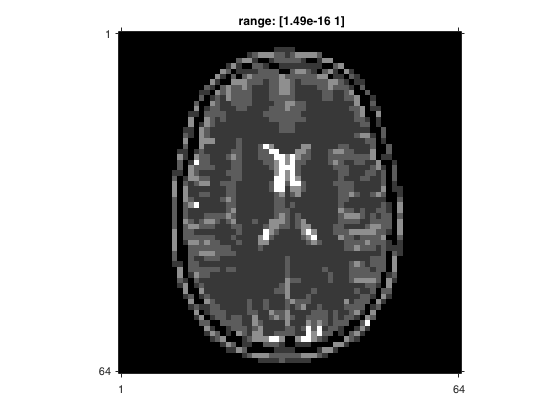

est0 = F_cart\y;    % compute a naive inverse (warning: slow)

% print nrmse to the ground truth and show image and difference image%
%nrmse(est0, x, 'Direct Inverse'),plt(est0, x, N_x, 'Direct Inverse Est.');

im(reshape(est0,[N_x,N_x])), colormap gray

As we can see on the left, we recover a very good representation of our original image. Congratulations, dear reader!

## Moving to non-Cartesian imaging

'Hey,' you think suddenly, 'I thought this was all about **NON**-Cartesian imaging. Everything sampled has been on the grid!'

You are correct, dear reader. I have not given you the non-Cartesian imaging introduction that has been promised. Let's fix that now.

To start, let's define a non-Cartesian trajectory. There are many non-Cartesian trajectories from which to choose. Like in most things, choice is a matter of satisfying requirements. Choosing the best non-Cartesian trajectory to use depends on the applications, and oftentimes involves as much personal preference, experience, and style as much as mechanics.

We'll start with the trusty spiral out trajectory. In a spiral out trajectory, we will start at the center of k-space and wind our way out to the edges of k-space. Every time you start the spiral trajectory with a new, fresh excitation of the system with an RF pulse, we call that a 'shot.' For this simulation, we will use one shot, commonly referred to as 'single shot imaging.' 

Designing a spiral trajectory is a complicated topic, requring adequate coverage of k-space to satisfy the Nyquist sampling theorem to avoid aliasing, respecting hardware limits in slew rates of the gradient amplifier, and maximum gradient amplitude available from the gradient amplifier. We will defer that discussion to the future (preferably never). There are several excellent articles on the subject, as well as several avaialble spiral generating routines in MATLAB and C code version on the internet.

We will generate a single shot spiral with settings that are reasonably achievable on a Siemens Prisma. It is necessary to fudge one detail: On a Siemens Prisma, the gradient system will only rasterize the waveform in 10 microsecond interval, of which the ADC will be operated at a much more reasonable 2 microsecond interval. We would normally interpolate the waveform to account for the discrepancy, but in this case we will assuming our ficticious gradient amplifer can handle a raster time of 2 microseconds. Your indulgence is much appreciated, dear reader.

As before, we will plot our trajectory to satisfy your curiosity.

% Perturbed variable density spiral
%N_k = 64^2;                         % number of k-samples
N_shots = 1;
N_FOV = 24; % cm
G_amp = 2.4; % gauss/cm - GE units
G_slew = 120; % also GE Units, but in mT/m
t_adc = 2E-6; % Not Siemens gradient raster time, typical ADC time

% Generate a spiral with typical parameters
[~,~,k_x, k_y] = genspi(N_FOV, N_x, N_shots,G_amp, G_slew, t_adc);

opfov = 24

Ts = 0.0217

matrix = 63.9640

maxg = 1.9387

maxs = 12.7331

maxt = 21.6540

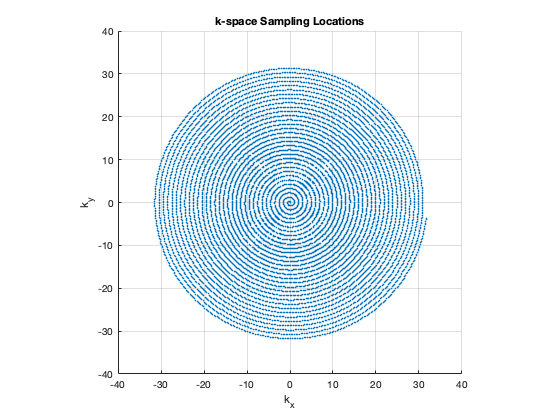


N_k = length(k_x);

% show scatterplot of trajectory
figure();scatter(k_x,k_y,5,'filled');axis square;grid on 
xlabel('k_x');ylabel('k_y');title('k-space Sampling Locations');drawnow;

## Define discrete Fourier encoding matrix

As in the Cartesian case, we need to generate our encoding matrix. This matrix is no longer the DFT matrix. It will not be square unless we have the particular (and rare) case where our image size matches the length of our k-space trajectory identically. As there is almost no reason for this to be the case, and many, many reasons for this not to be the case, it is safe to assume it will not be.

A more general term for $F_{\textrm{nonCart}}$ is the **system matrix. **System matrices are often denoted by $A\;$in the more general case.

[xidx, yidx] = meshgrid(-N_x/2 : N_x/2 - 1);  % x- and y-coords with "isocentre" at the N_x/2+1 index
xidx = xidx./N_x; %Scaling the window from 0.5 to -0.5
yidx = yidx./N_x;

% Loop over each k-location to construct its required spatial phase modulation
F_nonCart = zeros(N_k, N_x, N_x);
for i = 1:N_k
    F_nonCart(i,:,:) = exp(1j*2*pi*(k_x(i)*xidx+k_y(i)*yidx));   % 2D Fourier exponential
end

F_nonCart = reshape(F_nonCart, N_k, []);    % reshape F so that each row is a single k-space encoding

% show an example encoding
%figure();im(angle(reshape(F(N_k/2,:),N_x,N_x)),[-pi pi]), colormap hsv ; 
%title('Phase of Example 2D Fourier Encoding Modulation');colorbar();drawnow;

## Perform forward encoding/measurement

Dear reader, we will commit the inverse crime again. 

y = F_nonCart * x(:); % multiply encoding matrix with image vector to get data

## Solve the non-Carteisan Problem

Now, we have our system matrix, and our data, we can obtain our image. Easy, right?

est1 = F_nonCart \ y;    % compute a naive inverse (warning: slow)

warn im: magnitude of complex image


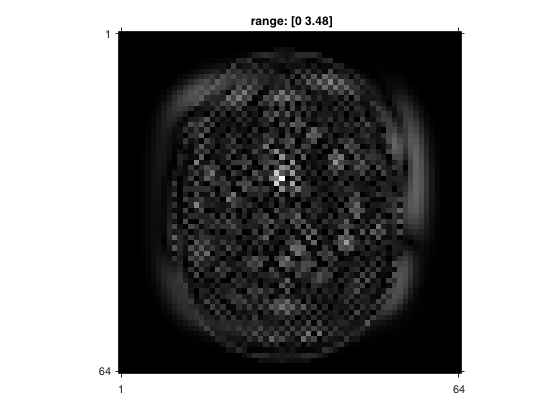

im(reshape(est1, [N_x,N_x])), colormap gray

## Post-mortem

Now, dear reader, I'm assuming that you may be feeling as though I have walked you into a finely laid trap. 

You are not wrong. However, I would suggest that it was not ***I *** that laid this trap, but the cruelty of the universe, or rather mathematics. 

Something has gone wrong, and that something can be found in the system matrices that we have obtained for the Cartesian and non-Cartesian problems. 

For this, I must beg your indulgence, dear reader, and digress along another tangent path.

## **The Condition Number for Inversion**

From linear algebra (or unheeded MATLAB warning messages), you may remember a quantity called the "condition number" that describes a matrix. The condition number can be defined several ways, including in terms of the singular value decomposition of a matrix. In terms of the singular values, it is the ratio of the largest singular value to the smallest singular value.

Conceptually, one useful interpretation for systems like our, such as $y=A\;x\;$, is that the condition number of $A\;$describes how small changes in $x$ are represented in $y$. For a minimal condition number, 1, small changes in $x$ result in small changes in $y$. However, if the condition number is quite large, then small changes in $x$ could result in huge changes in $y$. 

It is important to remember, that conditioning is primarily a numerical issue. If the condition number is finite (i.e. not infinite) then the matrix is invertable (if square). In such cases, it may not be inverted with any accuracy on a computer with limited numerical precision, and perhaps inverting the matrix is a very bad idea, but it is possible. It takes no more computer operations to invert an ill-conditioned matrix as a well-conditioned matrix, although, dear reader, you may not like the result.

For further discussion on the matter, I refer you to this link for a very accessible discussion: [https://blogs.mathworks.com/cleve/2017/07/17/what-is-the-condition-number-of-a-matrix/](https://blogs.mathworks.com/cleve/2017/07/17/what-is-the-condition-number-of-a-matrix/)

## **Back to our problem**

Now, dear reader, with that tangent concluded, let us return to our problem at hand: Why did the non-Cartesian problem fail to reconstruct well?

With the discussion of condition number in hand, let us start there.

**Cartesian Case:**

fprintf(1,'Cartesian Condition number: %3.2G\n',cond(F_cart)); % condition number of F_cart

Cartesian Condition number:   1


**non-Cartesian Case:**

fprintf(1,'non-Cartesian Condition number: %3.2G\n',cond(F_nonCart)); % condition number of F_nonCart

non-Cartesian Condition number: 3.6E+15


Ah-ha! Something appears very off, you think. 

And, dear reader, you would be correct. 

Our Cartesian case was perfectly well conditioned, with a condition number of an as-good-as-it-can-get 1.0. Our non-Cartesian case was... not. In fact, it is quite poorly conditioned, even ill...conditioned. 

## Enter... regularization

In fact, our non-Cartesian case is an ill-conditioned problem. For ill-conditioning, if you can't change the system matrix to make the entire process well-conditioned, then we must modify our problem formulation. We can do this by adding a **regularizer**, to impose some condition on the solution. One of the most basic forms of regularization is Tikhonov regularization.

In regularization, we now have to minimize two different objectives:

- Data fidelity, often written mathematically as ${\left\|y\;-\textrm{Fx}\right\|}_2^2$

- And a penalty term, in the Tikhonov case given by ${\left\|\textrm{Rx}\right\|}_2^2$, where $R$ is some linear operator (often a matrix)

The data fidelity term is almost always the same, but the penalty term is quite flexible. The choice of the operator or regularizer, $R$, can be quite creative and draw on prior information about the image. Dear reader, with any luck we will return to this topic in a future discussion.

When trying to balance multiple objectives, we now have an optimization problem, and can turn to the method of Lagrange multipliers. Our objective function is written below, with the introduction of the regularization constant, $\beta \ldotp$


$${C\left(x\right)=\left\|\textrm{Fx}-d\right\|}_2^2 +\beta {\left\|R\;x\right\|}_2^2$$


The regularization constant will control the balance between the data fidelity term and the penalty, and is a free parameter to be chosen by the user. Choose well, dear reader.

Optimizing our objective function can be done like any linear equation, starting with obtaining the gradient function.


$$\nabla C\left(x\right)={2F}^* \left(\textrm{Fx}-y\right)+2\beta R^* \left(R\;x\right)$$



$$\nabla C\left(x\right)={2F}^* \textrm{Fx}-{2F}^* y+2\beta R^* R\;x$$


$\nabla C\left(x\right)=0$ means that


$$F^* \textrm{Fx}-F^* y+\beta R^* R\;x=0$$



$$\left(F^* F+\beta R^* R\right)x=F^* y$$



$${x=\left(F^* F+\beta R^* R\right)}^{-1} F^* y$$


In this case, we chose the simplest L2 regularizer possible, which is the identity matrix. This penalizes the energy of the image, and can be thought to prevent the image from "blowing up" as they say.

beta  = 1E-4; % regularisation weighting
E       = (F_nonCart'*F_nonCart+beta*eye(N_x^2))\F_nonCart'; % compute linear estimator (warning: slow)

fprintf(1,'Condition number: %3.2G\n',cond(E)); % condition number of E

Condition number: 1.9E+11


warn im: magnitude of complex image


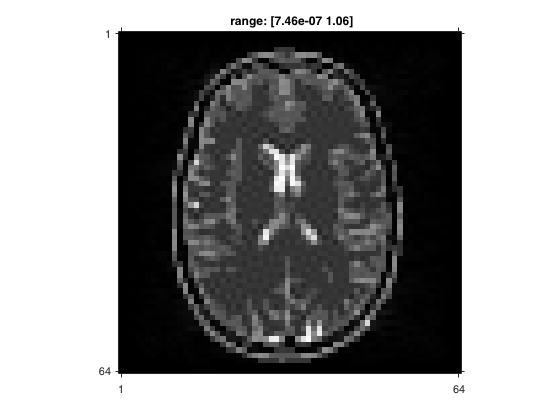

est2    = E*y;   % regularised reconstruction
im(reshape(est2,[64,64]))

Much better! We have now obtained a reasonable reconstructed image even in the face of ill-conditioning. We have also seen that the condition number got better once we introduced regularizaton. However, we formed a system matrix directly, and took a fairly expensive matrix inverse that is only possible on very small image reconstruction problems.

## Iterative Regularised Least Squares

Because direct inversion is still slow and costly, we can solve the same cost function with no explicit inverse operations, by using iterative schemes. Lets consider the simplest case of a steepest gradient descent algorithm:


$$x^{n+1} =x^n -\mu \nabla C\left(x^n \right)$$


where $x^n$ is the $n^{\textrm{th}}$ estimate of $x$, $\mu$ is a step size, and $\nabla C\left(x^n \right)$is the gradient of the cost evaluated at $x^n$. 

As a reminder, the gradient $\nabla C$ was:


$$\nabla C\left(x\right)={2F}^* \left(\textrm{Fx}-y\right)+2\beta R^* \left(R\;x\right)$$


Here, we continue using $R=I$, and we define a small fixed step size for simplicity. We define a maxinum number of iterations, but will stop iterating if the relative change in our estimate $x^n$ is small enough.

warn im: magnitude of complex image


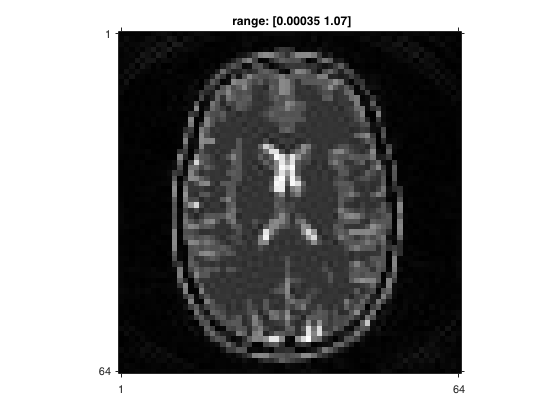

% define the gradient as a function, grad(x) = gradient(C(x))
%grad = @(x) (F_nonCart'*F_nonCart + beta*eye(N_x^2))*x - F_nonCart'*y;

% For computational reasons
R = beta*eye(N_x^2);
b = F_nonCart'*y;
FTF = F_nonCart'*F_nonCart;
FTFR = FTF + R;

grad = @(x) FTFR*x - b;

% define a fixed step size, max number of iterations, and relative change tolerance
step = 1E-6;
iter = 1000;
tol  = 1E-6;

% define an initial guess (starting point)
est3 = zeros(N_x^2,1);

% gradient descent function defined at the bottom
% ===================================================================
%{ 
function x = grad_desc(x, grad, step, max_iter, tol)
% steepest gradient descent
    ii = 0;                          % iteration counter
    dx = inf;                        % relative change measure
    while ii < max_iter && dx > tol  % check loop exit conditions
        tmp = step*grad(x);          % compute gradient step
        dx  = norm(tmp)/norm(x);     % compute relative change metric
        x   = x - tmp;               % update estimate
        ii  = ii+1;                  % update iteration count
    end
end
%}
% ===================================================================

% run through steepest gradient descent 
est3 = grad_desc(est3, grad, step, iter, tol);

figure; im(reshape(est3,[N_x, N_x])), colormap gray

## Conclusion

Thank you for your patience, dear reader, as we have walked through this hopefully gentle introduction to iterative reconstruction. Along the way we have encountered several pitfalls including ill-conditioned problems, very large, memory hungry matrices, and the need for iterative algorithms.

With this introduction, it is my fervent hope that you will have some of the tools to start understanding some of the many iterative reconstruction algorithms used in non-Cartesian imaging. 

Until next time!

## Helper Functions

function x = grad_desc(x, grad, step, max_iter, tol)
% steepest gradient descent
    ii = 0;                          % iteration counter
    dx = inf;                        % relative change measure
    while ii < max_iter && dx > tol  % check loop exit conditions
        tmp = step*grad(x);          % compute gradient step
        dx  = norm(tmp)/norm(x);     % compute relative change metric
        x   = x - tmp;               % update estimate
        ii  = ii+1;                  % update iteration count
    end
end

function nrmse(x,y,s)
% normalised root-mean-square error
    fprintf(1,'%s NRMSE: %f\n',s,norm(x(:)-y(:))/norm(y(:)));
end
